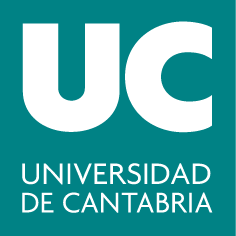

#### ***Grado en Ingeniería Química***

## **G320: Álgebra**

# **Práctica 6: Espacios vectoriales (I)**

*Rodrigo García Manzanas (rodrigo.manzanas@unican.es)*

*Valvanuz Fernández Quiruelas (valvanuz.fernandez@unican.es)*

**Objetivos**

- Determinar si un conjunto de vectores es libre o ligado

- Obtener una base de un subespacio

- Pasar de la forma implícita de un subespacio a la paramétrica y viceversa

**Dependencia e independencia lineal**

Sea el conjunto de vectores $$S=\lbrace (5,-9,6,4), (-3,4,-2,-1), (0,-7,8,7), (2,0,4,1)\rbrace$$de $\mathbb{R}^4$. Sabemos que $S$ será libre si para expresar el vector $(0,0,0,0)$ como combinación lineal de los vectores que lo componen se necesita que todos los coeficientes de la combinación sean nulos. Esto equivale a comprobar que el sistema homogéneo que tiene por matriz de coeficientes los vectores de $S$, colocados por columnas, tenga tan sólo la solución trivial (si tuviera infinitas soluciones, $S$ sería un conjunto ligado). Por tanto, dado un conjunto de vectores, bastará con calcular su rango para determinar si es libre o ligado.

% defino los vectores del conjunto
u1 = [5 -9 6 4]';
u2 = [-3 4 -2 -1]';
u3 = [0 -7 8 7]';
u4 = [2 0 4 1]';

% clasifico el sistema homogéneo de interés
S = [u1 u2 u3 u4]  % matriz de coefs. 
rank(S)  % R-F: S.C.I. -> el conjunto S es ligado

El comando *rank *nos indica cuál es el número de vectores independientes (en este caso tres, por lo que habrá un cuarto vector que depende linealmente de los otros tres), pero no cuáles. Podemos averiguar qué vectores del conjunto inicial son linealmente independientes a través de la escalonada reducida de la matriz que forman al colocarlos por columnas, puesto que las columnas pivotales identifican los vectores linealmente independientes. El resto de columnas indican la combinación lineal según la cual los vectores dependientes se pueden expresar en función de los independientes, siendo el $i-ésimo$ elemento de la columna el coeficiente que acompaña al $i-ésimo$ vector independiente.

rref(S)  % identifico u1, u2 y u4 como L.I. (columnas pivotales)
% el vector u3 depende linealmente de u1 y u2, de la siguiente forma:
% u3=3*u1+5*u2

***Nota******:*** *Siempre colocaremos los vectores de cualquier conjunto del que queramos estudiar su dependencia/independencia lineal en columnas.*

Podríamos haber llegado a la misma conclusión resolviendo el sistema homogéneo que tiene por matriz de coeficientes los vectores de $S$ colocados por columnas. De la solución devuelta por *null* se extraen directamente las relaciones de dependencia que se establecen entre los vectores del conjunto.

***Nota***: Una relación de dependencia lineal entre $n$ vectores $\vec{u}_i$ es una ecuación de la forma $c_1\vec{u}_1+ \cdots +c_n\vec{u}_n=0$ en la que los coeficientes $c_i$ no son todos nulos a la vez.

null(S, 'r') % relación de dependencia: -3*u1-5*u2+1*u3+0*u4 = 0

***Nota******:*** *Si el conjunto fuese libre, null devolvería como respuesta "empty matrix", que indica que la única solución del sistema es la trivial.*

**Obtención de una base de un subespacio**

Si el subespacio viene dado por sus ecuaciones paramétricas, una base del mismo sería directamente la formada por los vectores cuyas componentes son los coeficientes de los parámetros. Por ejemplo, para el subespacio $S$ de $\mathbb{R}^5$: 


$$S = \lbrace (2\alpha + 3\beta, 2\beta - \gamma, -3\alpha + \beta, -\gamma,\beta)  : \alpha, \beta, \gamma \in \mathbb{R} \rbrace$$
 

Una base sería $\lbrace (2,0,-3,0,0), (3,2,1,0,1), (0,-1,0,-1,0) \rbrace$.

baseS = [2 0 -3 0 0; 3 2 1 0 1; 0 -1 0 -1 0]'  % coloco los vectores 
% de la base en columnas

***Nota******:*** *Como convenio, siempre que introduzcamos por teclado una base colocaremos los vectores que la componen en columnas.*

Si, por el contrario, lo que se conoce del subespacio son sus ecuaciones implícitas, podrá obtenerse una base del mismo resolviendo el sistema homogéneo que constituyen dichas ecuaciones. Por ejemplo, en el caso del subespacio $T$ de $\mathbb{R}^4$:


$$T:\textstyle\left\{  \begin{array}{rcr}
			 x-y+2z +3t & = & 0\\ 
			 3x-2y+z-t & = & 0\\			
		 \end{array}\right.$$


coefImpT = [1 -1 2 3; 3 -2 1 -1];  % matriz de coefs. del sistema homogéneo
baseT = null(coefImpT, 'r')  % las columnas forman una base de T: {(3,5,1,0), 
% (7,10,0,1)}

**Paso de la forma implícita de un subespacio a la paramétrica**

Sea $S$ un subespacio de $\mathbb{R}^4$ dado en su forma implícita, $S: \left.
x + y - z - t = 0 \atop
2x + 2y - z - t = 0
\right\} $. Acabamos de ver que para obtener una base del mismo bastará con resolver el sistema homogéneo que forman sus ecuaciones implícitas. 

coefImpS = [1 1 -1 -1; 2 2 -1 -1];  % matriz de coefs. del sistema homogéneo
baseS = null(coefImpS, 'r')  % cada columna es un vector de la base de S

Por tanto, la forma paramétrica que busco será $S=\lbrace (-\alpha, \alpha, -\beta, \beta): \alpha, \beta \in \mathbb{R} \rbrace$.

**Paso de la forma paramétrica de un subespacio a la implícita**

Sea $S$ un subespacio de $\mathbb{R}^4$ dado en su forma paramétrica, por ejemplo $S = \lbrace (\alpha, \alpha, \beta, \beta): \alpha, \beta \in \mathbb{R}\rbrace$. Sabemos que cualquier vector de $S$ (y en particular los vectores de la base) verificarán las ecuaciones implícitas del subespacio, cuya forma general será $Ax + By + Cz + Dt  = 0$. Por tanto, bastará con resolver el sistema homogéneo cuya matriz de coeficientes estará formada por los vectores de la base (colocados en filas), y en el que las incógnitas serán precisamente los coeficientes de las ecuaciones implícitas que buscamos: $A, B, C, D$.

baseS = [1 1 0 0; 0 0 1 1]';  % base de S (en columnas)
coefImpS = null(baseS', 'r')  % las columnas dan directamente los coefs. 
% de las eqs. implícitas

La expresión del subespacio en implícitas será por tanto $S: \left.
-x + y= 0 \atop
-z + t  = 0
\right\} $

#### Ejercicios propuestos

**Ejercicio 1:**

Comprueba si los siguientes conjuntos de vectores de $\mathbb{R}^5$ son libres o ligados. 

- *a)* $A = \lbrace (1,0,1,2,1), (0,1,0,-1,3), (1,0,-1,0,5) \rbrace$

- *b)* $B = \lbrace (-2,4,0,-1,2), (2,1,2,-1,-1), (1,0,2,1,0), (0,1,-2,-3,1) \rbrace$

**Ejercicio 2:**

Encuentra las relaciones de dependencia lineal (en caso de haberlas) que se dan en el conjunto de vectores $S=\lbrace \vec{u_1}, \vec{u_2}, \vec{u_3}, \vec{u_4} \rbrace$, siendo $\vec{u_1}=(1,0,1,2)$,  $\vec{u_2}=(0,1,1,1)$,  $\vec{u_3}=(4,3,7,11)$ y  $\vec{u_4}=(-2,1,-1,-3)$. Comprueba que son correctas.

**Ejercicio 3:**

Dado el conjunto de vectores $S=\lbrace (1,0,-3,2), (0,1,2,-3), (-3,-4,1,6), (1,-3,-8,7), (2,1,-6,9) \rbrace$de $\mathbb{R}^4$:

- *a)* Halla las relaciones de dependencia que se establecen entre los vectores de $S$.

- *b)* Halla el valor (o valores) de $a$ para el que (los que) el vector $(a,4,-5,-10)$ se puede expresar como combinación lineal de los vectores linealmente independientes de $S$. ¿Cuáles son los coeficientes de esa combinación?

**Ejercicio 4:**

Halla una base de los siguientes subespacios de $\mathbb{R}^5$:

- *a) *$S=\lbrace (x,y,z,t,p) : x+y=0, z+t=0 \rbrace$ 

- *b) *$T=\lbrace x = -2\beta, y = 3\alpha - \gamma, z = \alpha - \gamma, t = -4\alpha + \beta - 2\gamma, p = \beta - 3\gamma  : \alpha, \beta, \gamma \in \mathbb{R} \rbrace$ 

**Ejercicio 5:**

Encuentra la forma paramétrica de los siguientes subespacios:

- *a) *En $\mathbb{R}^4$, $S: \left.
x + y + z + t = 0 \atop
y - 2z - t = 0
\right\} $

- *b) *En $\mathbb{R}^3$, $S:
x - 2y = 0 
$

- *c) *En $\mathbb{R}^4
$, $S: \left.
x = z \atop
y = t
\right\} $

**Ejercicio 6:**

Encuentra la forma implícita de los siguientes subespacios:

- *a) *En $\mathbb{R}^4$, $S = \lbrace (\alpha+\beta, \alpha+2\beta, -\beta, \beta): \alpha, \beta \in \mathbb{R}\rbrace$

- *b) *En $\mathbb{R}^3$, $S = \lbrace (\alpha+2\beta, -2\alpha+5\beta, -5\alpha+8\beta): \alpha, \beta \in \mathbb{R}\rbrace$

- *c) *En $\mathbb{R}^2$, $S = \lbrace (-\alpha+\beta, -2\alpha-\beta: \alpha, \beta \in \mathbb{R}\rbrace$